water.rho= 1000; %kg/m^3
Boat.rho= 500; %kg/m^3

Boat.HB= .1; % meters
Boat.D = .2 ; % meters, boat depth
Boat.L = .15 ;% length of boat in meters
Boat.dx= .001;
x_range= -Boat.L:Boat.dx:Boat.L; %in meters
y_range= -Boat.HB:Boat.dx:Boat.HB; % meters
z_range= 0:Boat.dx:Boat.D; %meters
%defining the outer bounds of the boat to create planes with meshgrid
[ygrid, zgrid] = meshgrid(y_range, z_range) ;
Boat.n= 900;



z= abs(y_range/Boat.HB).^Boat.n;
Boat.hull = zgrid > z;

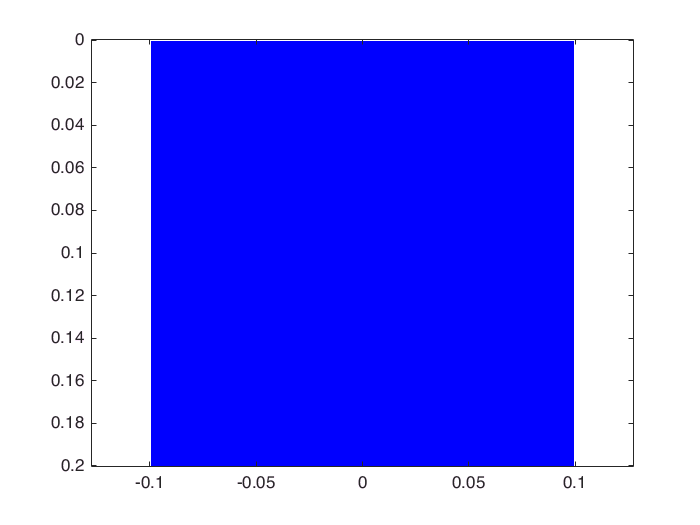

bluemap = [1,1,1; 0,0,1];
colormap(bluemap);
image(y_range, z_range,(Boat.hull))
axis('equal')

Boat.mass_cell = Boat.dx.^3 * Boat.rho; %mass per 1 mm cell cubic
% getting intitial center of mass for a uniformly dense cross-section of the boat
Boat.hull_masses = Boat.hull.*Boat.mass_cell;
Boat.mass = sum(Boat.hull_masses(:))

Boat = struct with fields:
            rho: 500
             HB: 0.1000
              D: 0.2000
              L: 0.1500
             dx: 1.0000e-03
              n: 900
           hull: [201×201 logical]
      mass_cell: 5.0000e-07
    hull_masses: [201×201 double]
           mass: 0.0199
          mass2: 0.0975


COM01= COMyz(Boat.hull_masses,ygrid,zgrid)

COM01 =    -0.0000    0.1005


%adding a mass at the bottom of the boat to lower the center of mass
pos.z = 0;
pos.y = 0;
% Boat.hull_masses = AddMassz(Boat.hull_masses,z_range, y_range,pos,.025);
%I had the boat with ballast added at one point but then I realized we weren't supposed to
COM1 = COMyz(Boat.hull_masses,ygrid,zgrid)

COM1 =    -0.0000    0.1005


Boat.mass2 = sum(Boat.hull_masses(:));
water.cell_rho = water.rho .* Boat.dx.^3; % this is the mass per cell of water- the density in terms of cells

sumberge1d= fzero(@OneDimBoat, .05)

sumberge1d = 0.0250

theta1 = 30;
fun1= @(b) massdiff(b,ygrid,zgrid,Boat,water,theta1);
bval = fzero(fun1, .1);
water_disp = submerge(ygrid,zgrid,Boat,water,bval,20);
image(y_range, z_range,(water_disp))
water.masses = water.cell_rho.*water_disp;
COB = COMyz(water.masses,ygrid,zgrid)

COB =     0.0120    0.0527


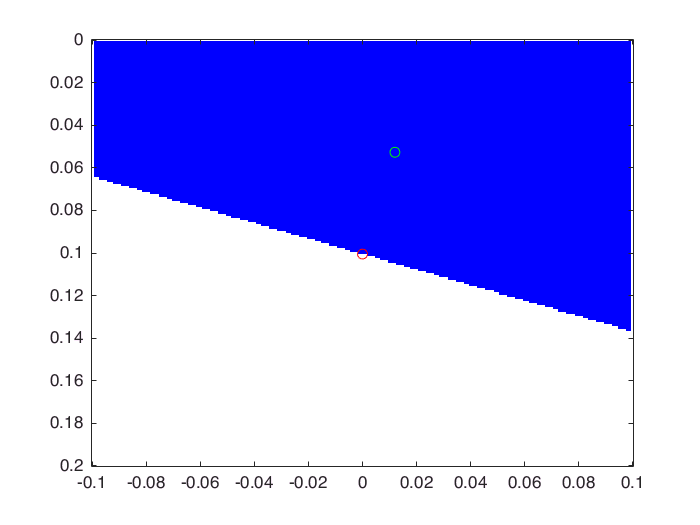

hold on; 
comy= COM1(1);
comz= COM1(2);
coby= COB(1);
cobz= COB(2);
plot(comy,comz,'ro')
plot(coby,cobz, 'go')

theta_range= [0:7:160];
CobsRange= RotateCOB(theta_range,Boat,water,ygrid,zgrid);
hold off

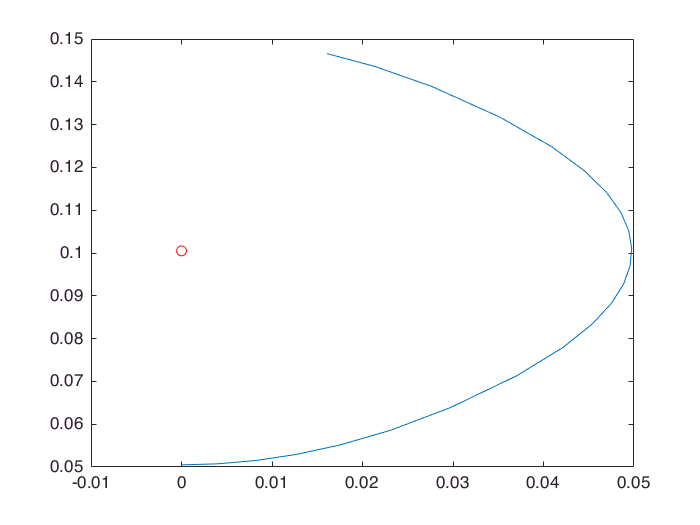

clf
plot(CobsRange(1,:), CobsRange(2,:))
hold on;
plot(COM1(1), COM1(2),'ro')
hold off;

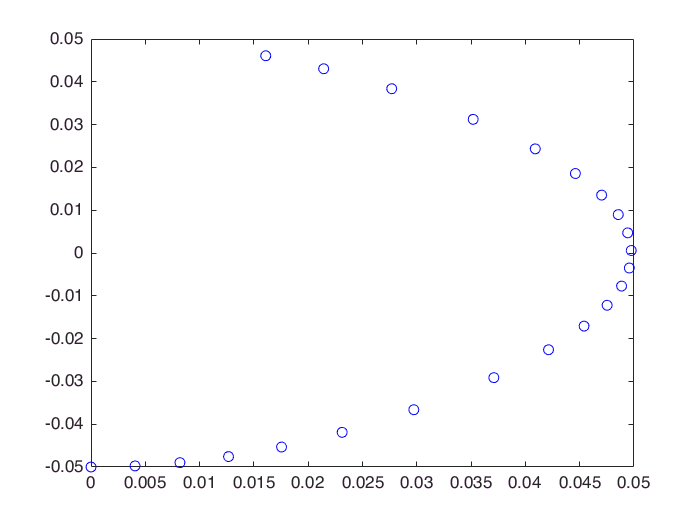

COMrangey = ones(1,length(theta_range)).*COM1(1); 
COMrangez= ones(1,length(theta_range)).*COM1(2);
RightingArmy= -COMrangey + CobsRange(1,:);
RightingArmz = -COMrangez + CobsRange(2,:);
clf
% This should plot the COB through a range of thetas with the center of mass at 0,0. The distance from the origin to 
%the COB should be the righting arm
plot(RightingArmy, RightingArmz,'bo')

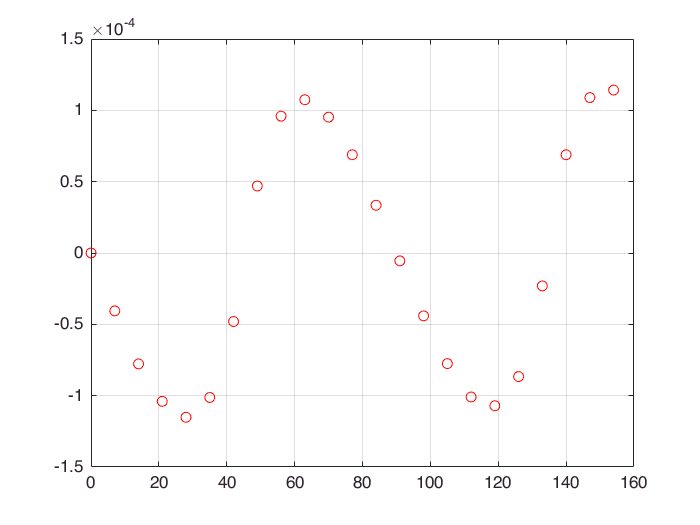

torques= BuoyantTorque(Boat,theta_range,COM1,CobsRange);
%ok unless i have completely gone off the rails I think this should be a plot of the magnitude of the torque 
% around the center of mass vs the heel angle. I think it follows the left hand rule or somehow I messed up the 
%direction of the torque? I don't know i could be really wrong
clf
plot(theta_range, torques(1,:),'ro')
grid on

function res = COMyz(masses, ygrid,zgrid)
    M = sum(masses(:));
    Y = masses.*ygrid;
    Z = masses.*zgrid;
    comy = sum(Y(:))./M;
    comz = sum(Z(:))./M;
    res = [comy,comz];
end

function index = ClosestIndex2(coord, grid)
   [c index] = min(abs(coord-grid));
end

function masses = AddMassz(masses,z_range,y_range,pos,mass)
    indexz= ClosestIndex2(pos.z,z_range);
    indexy= ClosestIndex2(pos.y,y_range);
    masses(indexz,indexy) = masses(indexz,indexy) + mass;
    
end

function out = OneDimBoat(waterline)
    mass1d= .10;
    area1d= .004;
    density1d= 1000;
        submergedmass= density1d*area1d*waterline;
        out= submergedmass - mass1d;
end


%This computes a logical matrix representing the area of water displaced 
function res = submerge(ygrid,zgrid,Boat,water,b,theta)
    fun = tand(theta).*ygrid +b;
    if theta < 90 | theta > 270
        W = zgrid < fun;
    else 
        W = zgrid > fun; 
    end 
    res = Boat.hull & W;
end


% this is fuction is mostly redundant, using it find the y intercept with fzero. returns 
%the mass of the displaced water minus the mass of the boat. When these are balanced, it should be in equilibrium.
function out = massdiff(b,ygrid,zgrid,Boat,water,theta)
    sub_r = submerge(ygrid,zgrid,Boat,water,b,theta);
    mass_sub= water.cell_rho.* sum(sub_r(:));
    out = mass_sub - Boat.mass2;
end 

function res = RotateCOB(theta_range, Boat, water, ygrid, zgrid) 
    L = length(theta_range);
    Y = zeros(1,L);
    Z = zeros(1,L);
    for i = 1:L
        theta = theta_range(i);
        func1= @(b) massdiff(b,ygrid,zgrid,Boat,water,theta);
        bval = fzero(func1, .01) ;
        water_disp = submerge(ygrid,zgrid,Boat,water,bval,theta);
        water.masses= water.cell_rho.*water_disp;
        COB = COMyz(water.masses, ygrid,zgrid); 
        Y(i) = COB(1);
        Z(i) = COB(2);
        
    end
    res= [Y; Z];
    
    
end 
%calculates the buoyant force, equal to the mass of the boat in the direction perp. to the water line, 
%using trig to get the componants of this in the base coordinate system.
function res = BuoyantForce(Boat,theta_range)
    FBy= zeros(1,length(theta_range));
    FBz= zeros(1,length(theta_range));
    FBx= zeros(1,length(theta_range));
    for i = 1:length(theta_range)
        theta= theta_range(i) + 90;
        FBy(i) = Boat.mass2.*cosd(theta);
        FBz(i) = Boat.mass2.*sind(theta);
    end
    res = [FBx; FBy; FBz];
end 
%Finds the torque around i hat for a boat with a given center of mass, and an established range of angles and centers of buyancy for those angles        
function res = BuoyantTorque(Boat,theta_range,COM,CobsRange) 
    L = length(theta_range);
    COMrangey = ones(1,length(theta_range)).*COM(1); 
    COMrangez= ones(1,length(theta_range)).*COM(2);
    RightingArmy= -COMrangey + CobsRange(1,:);
    RightingArmz = -COMrangez + CobsRange(2,:);
    RightingArmx = zeros(1,length(theta_range));
    RightArm = [RightingArmx; RightingArmy; RightingArmz];
    FBuoyant = BuoyantForce(Boat,theta_range);
    sz = size(RightArm);
    Torques = zeros(sz);
    for i = 1:L
        Torques(:,i) = cross(RightArm(:,i), FBuoyant(:,i));
    end
    res= Torques;
    
end 